addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01

t_end = 0.0200

t = 0 : t_step : t_end

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% generate figure noisy_optimising
%{
n = 40;
taus = logspace(-5, 0, n);
chi2s = zeros([1, n]);
parfor i = 1 : n
    chi2s(i) = to_minimise(taus(i));
end

figure
scatter(taus(i), m)
set(gca,'Xscale','log','Yscale','log')
hold on
[m, i] = min(chi2s);
taus(i)
scatter(taus(i), m)
%}

%{
figure
loglog(taus, chi2s)
hold on
[m, i] = min(chi2s);
scatter(taus(i), m)
%}

%power_ratios = linspace(7.2e-3, 7.2e-4, 2)
power_ratios = 1

power_ratios = 1

noise_ratio = 1.0000e+08

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 10).

                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              10       5.033e+11       5.464e+11        0
    1              20       1.476e+11       8.354e+11        0
    2              30       1.375e+11       8.485e+11        0
    3              40       1.375e+11       5.915e+11        1
    4              50       1.375e+11       7.352e+11        2
    5              60       1.375e+11       7.728e+11        3
    6              70       1.375e+11       1.197e+12        4
    7              80       1.375e+11       6.021e+11        5
    8              90       6.781e+10       4.498e+11        0
    9             100       6.781e+10       7.703e+11        1
   10             110       5.774e+10       6.386e+11        0
   11             120       5.774e+10       6.641e+11  

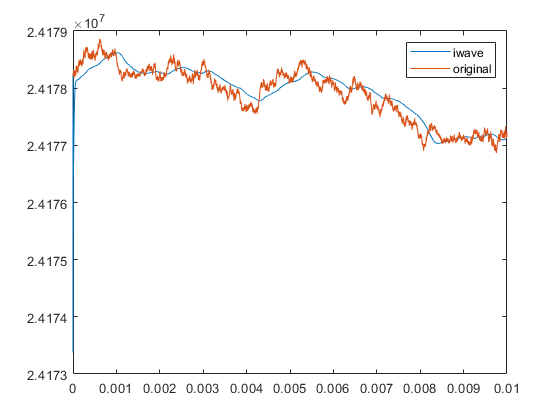

T = 1

ans = 10

noise_in_band = 2.5780e-19

signa_in_band = 5.9713e-22

tau_res = 9.4383e-06

axion_power = 1e-21;

reps = 1;
tau_res = zeros([length(power_ratios), reps]);

band = [f_a-500, f_a+500];

for rep = 1 : reps
    
    %% generate axion frequency
    f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);
    
    %% generate signal and noise
    signal = calc_wave_with_frequency(t, f_sampling, f_axion);
    signal = signal / sqrt( bandpower(signal, f_sampling, band) ); % get signal power in band = 1
    noise = randn(size(t));
    noise = noise / sqrt(bandpower(noise, f_sampling, band));

    for i = 1 : length(power_ratios)
        signal_in = signal * sqrt(power_ratios(i)) * 10000;
        
        noise_ratio = bandpower(signal_in, f_sampling, band) / bandpower(noise, f_sampling, band)
        
        tau_res(i, rep) = get_tau(f_sampling, t, signal_in, noise, f_a, f_axion) % f_0 = f_a for the mo
    end
end



% 21 iter takes 5 min
% 60 sec - 3.1106 default swarm size
% no time lin, default tolerance - 0.084, 2.3319, 52 iter
% no time lin, 1e-4    tolerance - 0.084, 2.3323, 64 iter
% no time lin, 1e-3    tolerance - 0.084, 2.3176, 41 iter
% no time lin, 1e-2    tolerance - 0.084, 2.332 , 34 iter
% no time lin, 1e-1    tolerance - 0.084, 2.3041, 29 iter
% no time lin, 1e-1    tolerance - 0.084, 2.3454, 36 iter

%{
tau_avg = mean(tau_res,2)
tau_std = std(tau_res,0,2);
%}

% export the figure
%{
figure
adstyle(8, 8)
loglog(taus, chi2s)
xlabel('\tau')
ylabel('\chi^2')
[m, i] = min(chi2s);
hold on
scatter(taus(i), m)
%saveas(gcf, 'figures/noisy_optimisation.eps', 'epsc')
taus(i)
%}


function tau_iwave = get_tau(f_sampling, t, signal, noise, f_0, f_axion)
    %noise_pwr = bandpower(noise);
    
    % atm we're running iwave on the signal not the signal + noise
    iwave_in = signal + noise;
    
    bandwidth = 750;
    iwave_input = prepare_iwave_input(iwave_in, f_0, bandwidth, f_sampling);
    
    % check
    %f = run_iwave(iwave_input, f_sampling, f_0, 1e-4);
    %plot(t, f)
    %hold on
    %plot(t, f_axion)
    
    % front to chop off
    start_secs = t(end)/4;
    start = start_secs * f_sampling;
    assert(start_secs < t(end)/3)
    
    chop = @(arr) arr(start:end);
    to_minimise = @(tau) sum(power(chop(f_axion - run_iwave(iwave_input, f_sampling, f_0, tau)), 2));
    
    options = optimoptions(@particleswarm, 'Display','iter', 'UseParallel',true, 'FunctionTolerance', 0.1);
    [x,fval,exitflag,output] = particleswarm(to_minimise, 1, 1e-6, t(end), options);
    
    % check
    f = run_iwave(iwave_input, f_sampling, f_0, x);
    figure
    plot(t, f)
    hold on
    plot(t, f_axion)
    legend('iwave', 'original')
    
    tau_iwave = x;
end